# PHYS 361: Lab 4

## Warm Up:

We will work together to produce a plot of real data taken by CWU students during the annular eclipse on October 14th, 2023.

First, use [readtable](https://www.mathworks.com/help/matlab/ref/readtable.html?s_tid=doc_ta) to import the from the file called Ground_Station_Data.xlsx and save it as a table named grounddata. *Read the documentation carefully to examine the first 5 rows of the data.* You may want to test code in the command line.

grounddata = readtable("ground_station_data.xlsx");

Next, we will take the column labeled TIMESTAMP and convert it to a  [datetime](https://www.mathworks.com/help/matlab/ref/datetime.html?s_tid=doc_ta) variable. This is a variable type specifically for data that represents time and dates (just like it sounds). How the date and time is specified in a data set can vary, so we will need to tell MATLAB exactly how the date and time is formatted in the TIMESTAMP column. *Can you read the documentation to figure out how to specifiy the format of the data using a line similar to this one given in the documentation *[`t = datetime(DateStrings,'InputFormat',infmt)`](https://www.mathworks.com/help/matlab/ref/datetime.html?s_tid=doc_ta#d126e335097)`?` Once we have figured that out, we will save the data in the TIMESTAMP as a new variable called time by specifying the format of the data.

time = datetime(grounddata.TIMESTAMP, InputFormat="dd-MMM-yyyy HH:mm:ss");

Now we will save the data from the column labeled AirTemp_C as a new variable called tempC. We will have to do a little extra work because AirTemp_C was imported as a string, so we have to tell MATLAB to convert that data to a numerical data type known as a double. Can you do a google or documentation search to figure out how to do that?

tempC = grounddata.AirTemp_C;

Convert the temperature in Celcuis to Fahreneit.

tempF = (9/5).*tempC + 32;

Make a quick plot of the time versus the temperature in Fahreneit. Notice that MATLAB knows how plot the datetime variable.

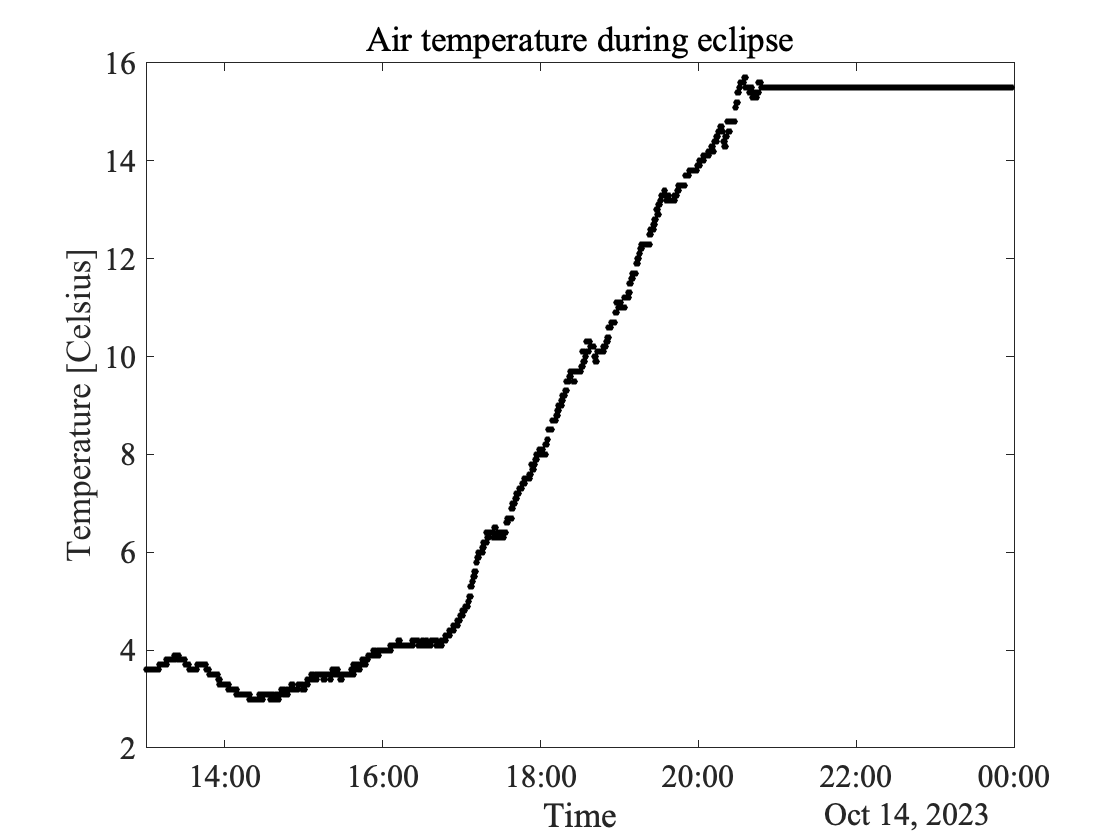

s = scatter(time, tempC, 12, "filled", "ok");
s.Parent.Box = "on";
s.Parent.FontWeight = "normal";
s.Parent.FontName = "Times New Roman";
s.Parent.FontSize = 16;
xlabel("Time");
ylabel("Temperature [Celsius]");
title("Air temperature during eclipse", FontWeight="normal")
exportgraphics(gcf, "eclipse_airtemp.pdf");

Finally, lets practice outputting some data by creating a text file that contains just two columns of data.  The first column will be the amount of time that has passed since the first data point in seconds. The second column of data will be the temperature in Fahreneit.

% calculate time difference
time_diff = seconds(time - time(1));

% output data to file
fileID = fopen("time_tempc.txt", "w+");
fprintf(fileID, '%s %s\n', 'seconds elapsed', 'tempC');
fprintf(fileID, '%10.1f %10.1f\n', [time_diff.'; tempC.']);
fclose(fileID);

## Problem 1:

For this problem, you will make an Hertzsprung-Russell diagram using a set of star data taken from a catelog.

**Directions:**

- Download the file Star_Data.xlsx from the Canvas Module. 

- Import the data into the Live Script. Save the columns with the absolute magnitude (Abs Mag) and the B-V Color Index into their own column vectors.

- Calculate the temperature of each star from their B-V Color Index using the following formula.

                    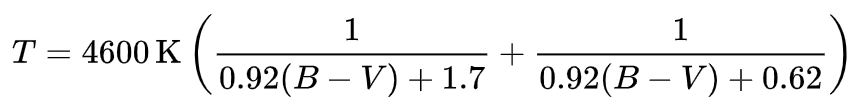

*By the way the B-V color index represents the difference in brightness of the star in two common filters (the blue and visible). The differences in these filters depends on the properties to the blackbody curve of the star. The blackbody curve is determined by the stellar temperature.*

3. Make a [scatter plot ](https://www.mathworks.com/help/matlab/ref/scatter.html)using the data. The B-V index should be on the horizontal axis and the absolute magnitude should be on the vertical axis. 

4. Improve your plot by having the color of the markers should indicate the temperature of the star.  

5. Further improve your plot by adjusting the limits of the axes and including appropriate axes labels.  Change the font size so the axes labels are easy to read.

6. Use [saveas](https://www.mathworks.com/help/matlab/ref/saveas.html?s_tid=doc_ta) to save your new figure at the end of your program.

***Extra****: If you want to get fancy you could set the size of the markers to show the apparent magnitude of the star. Stars that look brighter to a person on Earth will have a more negative apparent magnitude.*

% load data
star_data = readtable("star_data.xlsx");

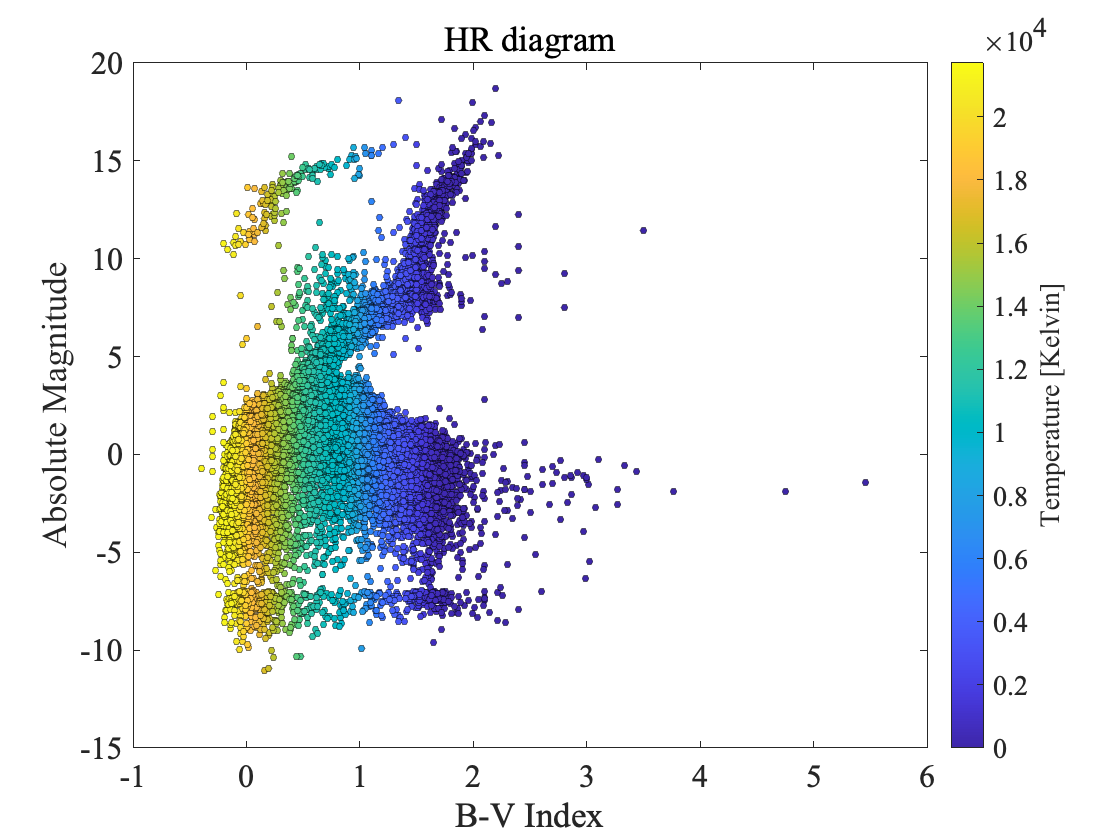


% extract some data
abs_mag = star_data.AbsMag.';
BV_index = star_data.ColorIndexB_V.';

% calculate star temp [Kelvin]
star_temp = 4600*( (1 ./ ( 0.92.*BV_index + 1.7 )) + (1 ./ ( 0.92.*BV_index + 0.62 )) );

% define colorbar
pt_color = parula(numel(star_temp));
[~, temp_sort] = sort(star_temp);
pt_color(temp_sort, :) = pt_color;

% scatter plot
s = scatter(BV_index, abs_mag, 12, pt_color, "filled", "o");

% define plotting visual preferences
s.Parent.Box = "on";
s.Parent.FontWeight = "normal";
s.Parent.FontName = "Times New Roman";
s.Parent.FontSize = 16;
s.MarkerEdgeColor = "k";
s.MarkerEdgeAlpha = 0.5;

% remove the exponent on x-axis
ax = ancestor(s, 'axes');
ax.XAxis.Exponent = 0;
ax.XAxis.TickLabelFormat = '%.0f';

% add plot labels
xlabel("B-V Index");
ylabel("Absolute Magnitude");
title("HR diagram", FontWeight="normal");

% add colorbar
cb = colorbar;
ylabel(cb, "Temperature [Kelvin]");
clim([0, max(star_temp)]);

% save
exportgraphics(gcf, "hr_diagram.pdf");

## Problem 2: 

Let's make a plot that shows the vector velocity of a ball undergoing projectile motion (neglecting air resistance). 

Recall the kinematic equations used to calculate the trajectory (or the x and y-positions) of a ball undergoing projectile motion are as follows:


$$x=x_0+v_{x0}t$$



$$y=y_0+v_{y0}t-\frac{1}{2}gt^2$$


where $x_0$ and $y_0$ are the initial positions in the x and y direction, $v_{x0}$ and $v_{y0}$ are the initial velocities in the x and y directions, and *g=*9.8 $m/s^2$ is the acceleration of gravity.

Write code that uses a for loop to calculate the x and y-positions from 0 to 2 s with $\Delta t=0.1$s and store them  in arrays. Set $v_{x0}=v_{y0}=10$ m/s. Plot the x and y positions against one another to produce a curve like the one shown at the end of this problem.

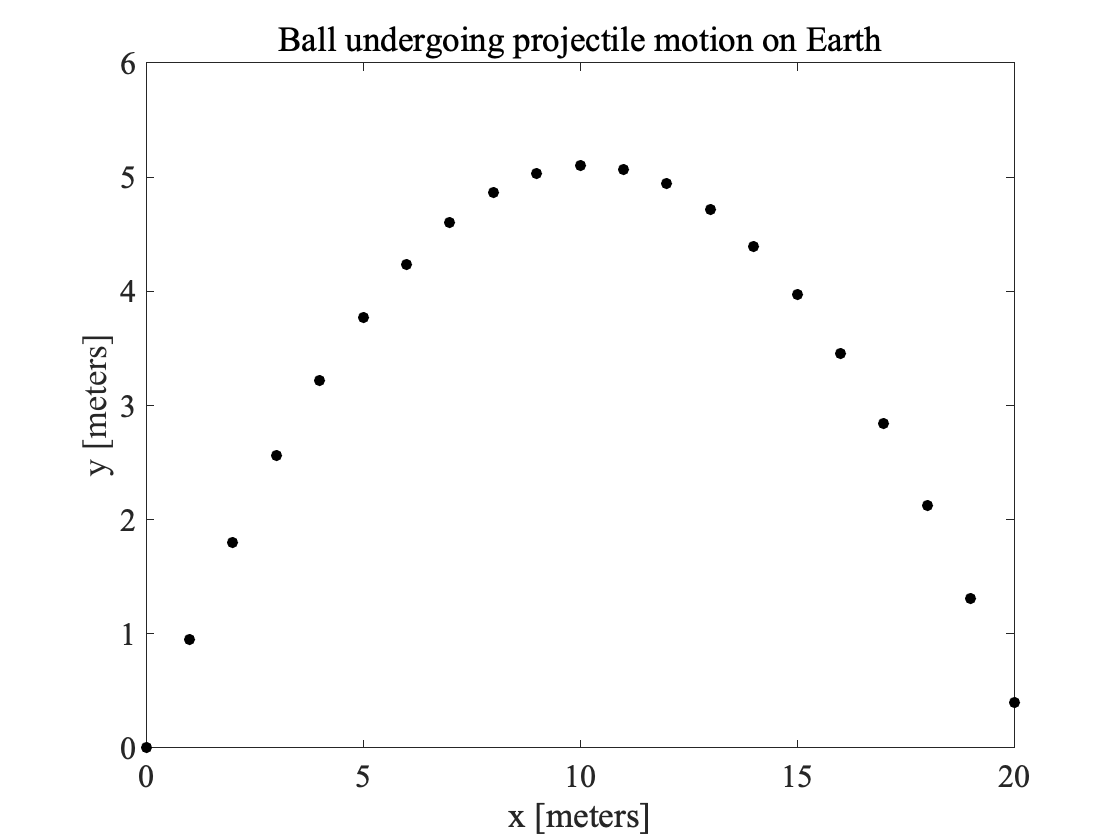

% set time information [seconds]
sim_time = 2;
time_step = 0.1;
time = (0 : time_step : sim_time).';

% define data arrays
pos = zeros(length(time), 2);

% set initial conditions
pos(1, :) = [0, 0];

% tunable parameters
% velocity [m/s]
vx0 = 10;
vy0 = 10;
% gravity [m/s^2]
g = 9.8;

% enter simulation
pos(:, 1) = pos(1, 1) + vx0.*time;
pos(:, 2) = pos(1, 2) + vy0.*time - (g/2).*(time.^2);

% plot positions
p = scatter(pos(:, 1), pos(:, 2), 32, "filled", "ok");
p.Parent.Box = "on";
p.Parent.FontWeight = "normal";
p.Parent.FontName = "Times New Roman";
p.Parent.FontSize = 16;
xlabel("x [meters]");
ylabel("y [meters]");
title("Ball undergoing projectile motion on Earth", FontWeight="normal");
exportgraphics(gcf, "projectile_motion.pdf");

Copy the code from above and paste it in the code cell below. Change your program so that the magnitude of the initial speed and its angle with respect to ground can be input by the user using an [input](https://www.mathworks.com/help/matlab/ref/input.html?searchHighlight=input&s_tid=srchtitle_support_results_1_input) prompt. Use the speed and angle to calculate the x and y-components of the initial velocity (i.e., calculate $v_{x0}$ and $v_{y0}$ rather than specify them). Use a while loop to calculate how the position of the projectile changes (x and y values) until it hits the ground (or is very close to hitting the ground). Again, plot the x and y positions against one another to produce a curve like the one shown at the end of this problem.

% get user input for speed and direction
spd_prompt = "Enter ball speed in m/s : "

spd_prompt = "Enter ball speed in m/s : "

dir_prompt = "Enter ball direction in degrees from the positive horizontal axis : "

dir_prompt = "Enter ball direction in degrees from the positive horizontal axis : "

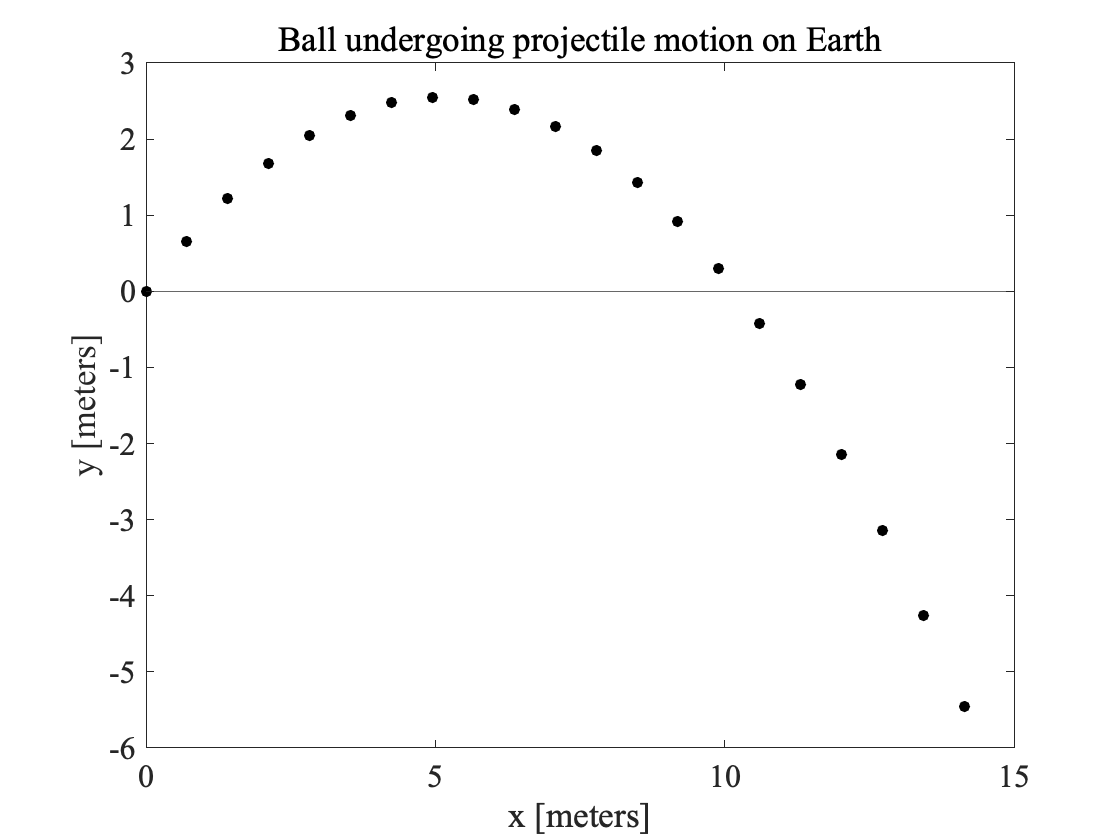

spd_input = input(spd_prompt);
dir_input = input(dir_prompt);

% set time information [seconds]
sim_time = 2;
time_step = 0.1;
time = (0 : time_step : sim_time).';

% define data arrays
pos = zeros(length(time), 2);

% set initial conditions
pos(1, :) = [0, 0];

% tunable parameters
% velocity [m/s]
vx0 = spd_input * cosd(dir_input);
vy0 = spd_input * sind(dir_input);
% gravity [m/s^2]
g = 9.8;

% enter simulation
pos(:, 1) = pos(1, 1) + vx0.*time;
pos(:, 2) = pos(1, 2) + vy0.*time - (g/2).*(time.^2);

% plot positions
p = scatter(pos(:, 1), pos(:, 2), 32, "filled", "ok");
yline(0);
p.Parent.Box = "on";
p.Parent.FontWeight = "normal";
p.Parent.FontName = "Times New Roman";
p.Parent.FontSize = 16;
xlabel("x [meters]");
ylabel("y [meters]");
title("Ball undergoing projectile motion on Earth", FontWeight="normal");
exportgraphics(gcf, "projectile_motion_userinput.pdf");

Copy and paste your code from above into the code cell below. Add code inside your while loop that calculates and stores how the *velocity* in the x and y direction changes with time. 

Next, use [quiver](https://www.mathworks.com/help/matlab/ref/quiver.html?searchHighlight=quiver&s_tid=srchtitle_support_results_1_quiver) to add a few velocity vectors to your plot, so it looks similar to the one below. You should read MATLAB's documentation to learn how to use [quiver](https://www.mathworks.com/help/matlab/ref/quiver.html?searchHighlight=quiver&s_tid=srchtitle_support_results_1_quiver)`.` You will also need to use [hold on](https://www.mathworks.com/help/matlab/ref/hold.html?searchHighlight=hold%20on&s_tid=srchtitle_support_results_1_hold%20on) and `hold off`. Galleries like this [MATLAB plot gallery](https://www.mathworks.com/products/matlab/plot-gallery.html) can also be helpful for figuring out how to make a particular type of plot.

Finally, add labels to the x and y axis and use [xlim](https://www.mathworks.com/help/matlab/ref/xlim.html?s_tid=doc_ta) and/or [ylim](https://www.mathworks.com/help/matlab/ref/ylim.html?searchHighlight=ylim&s_tid=srchtitle_support_results_1_ylim) to improve the appearance of your plot.

% get user input for speed and direction
spd_prompt = "Enter ball speed in m/s : "

spd_prompt = "Enter ball speed in m/s : "

dir_prompt = "Enter ball direction in degrees from the positive horizontal axis : "

dir_prompt = "Enter ball direction in degrees from the positive horizontal axis : "

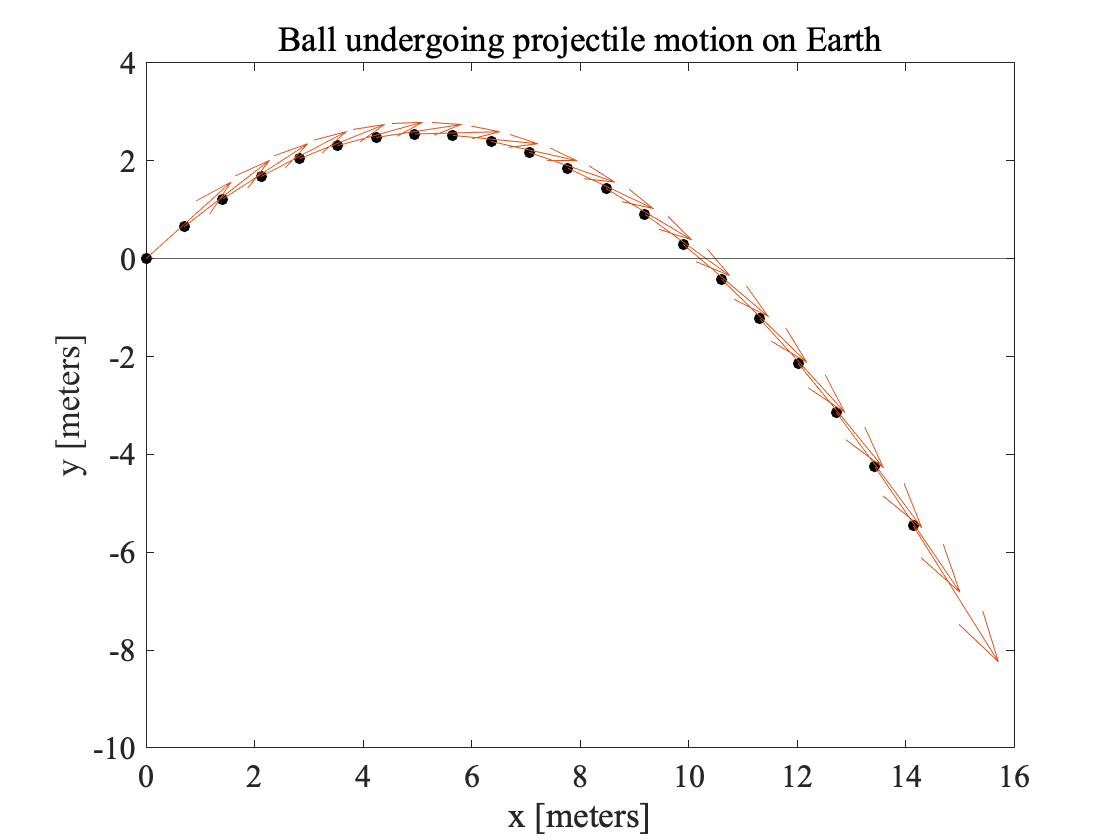

spd_input = input(spd_prompt);
dir_input = input(dir_prompt);

% set time information [seconds]
sim_time = 2;
time_step = 0.1;
time = (0 : time_step : sim_time).';

% define data arrays
pos = zeros(length(time), 2);
vel = zeros(length(time), 2);

% set initial conditions
pos(1, :) = [0, 0];

% tunable parameters
% velocity [m/s]
vx0 = spd_input * cosd(dir_input);
vy0 = spd_input * sind(dir_input);
% gravity [m/s^2]
g = 9.8;

% enter simulation
pos(:, 1) = pos(1, 1) + vx0.*time;
pos(:, 2) = pos(1, 2) + vy0.*time - (g/2).*(time.^2);
vel(:, 1) = vx0;
vel(:, 2) = vy0 - (g .* time);

% calculate vector dir and mag from displacements
% vel_vec = sqrt(vel(:, 1).^2 + vel(:, 2).^2);
% vel_ang = tan

% plot positions
p = scatter(pos(:, 1), pos(:, 2), 32, "filled", "ok");
hold on
yline(0);
p.Parent.Box = "on";
p.Parent.FontWeight = "normal";
p.Parent.FontName = "Times New Roman";
p.Parent.FontSize = 16;
quiver(pos(:, 1), pos(:, 2), vel(:, 1), vel(:, 2))
hold off
xlabel("x [meters]");
ylabel("y [meters]");
title("Ball undergoing projectile motion on Earth", FontWeight="normal");
exportgraphics(gcf, "projectile_motion_vectors.pdf");